## Load and setup data


clear all;

addpath(genpath('matlabfunctions'))
addpath(genpath('/Applications/MATLAB_TOOLBOXES'))

load('./completeData/human_data.mat')
load('./completeData/monkey_data.mat')

load('./data/monkey_fig_data.mat')
load('./data/monkey_fig_region_data.mat')

load('./data/human_fig_data.mat')
load('./data/human_fig_region_data.mat')

fig_data = struct;
fig_data.monk_data = monkey_fig_data;
fig_data.monk_region_data = monkey_fig_region_data;
fig_data.human_data = human_fig_data;
fig_data.human_region_data = human_fig_region_data;

save('./data/figure_data.mat','fig_data')

% Human Labels
human_labels = human_data.labels;
human_areadistfromV1 = human_data.areadistfromV1;
human_fellemanhierarchy = human_data.fellemanhierarchy;

% Monkey Labels
monkey_data.labels

ans = 1×26 cell array
    {'V1v'}    {'V1d'}    {'V2v'}    {'V2d'}    {'V3v'}    {'V3d'}    {'V4v'}    {'V4d'}    {'V4Av'}    {'V4Ad'}    {'OTd'}    {'PITv'}    {'PITd'}    {'OTS1'}    {'OTS2'}    {'V3A'}    {'DP'}    {'MT'}    {'MST'}    {'FST'}    {'V4t'}    {'CIP1'}    {'CIP2'}    {'LIP1'}    {'LIP2'}    {'LIP3'}


monk_areadistfromV1= monkey_data.areadistfromV1;
monk_fellemanhierarchy= monkey_data.fellemanhierarchy;
monks_allareas=monkey_data.V1_cat_corr1234;

% Make 0 sum ROIs -> NaN
for i = 1:2
    human_data.surfacearea_smoothwm{i}(human_data.surfacearea_smoothwm{i}==0)=nan;
    human_data.surfacearea_pial{i}(human_data.surfacearea_pial{i}==0)=nan;
end

% get average of white matter and pial surface area
human_surfacearea_avg = cellfun(@(x,y) (x+y)/2, human_data.surfacearea_smoothwm, human_data.surfacearea_pial,'UniformOutput',false);
human_bothhemi_SA = [human_surfacearea_avg{1}, human_surfacearea_avg{2}];

% restructure summed hemisphere data to get area categories we want to display
V1_sumhemis_sumvd = human_bothhemi_SA(1,:) + human_bothhemi_SA(2,:);
V2_sumhemis_sumvd = sum(human_bothhemi_SA(3:4,:),1);
V3_sumhemis_sumvd = sum(human_bothhemi_SA(5:6,:),1);
V4_sumhemis_sumvd = human_bothhemi_SA(7,:);

SA_sumvd_human = [V1_sumhemis_sumvd;V2_sumhemis_sumvd;...
    V3_sumhemis_sumvd;V4_sumhemis_sumvd;human_bothhemi_SA(8:end,:)];


monks_avg{1} = (monkey_data.retino_surfacearea_pial{1} + monkey_data.retino_surfacearea_smoothwm{1})/2;
monks_avg{2} = (monkey_data.retino_surfacearea_pial{2} + monkey_data.retino_surfacearea_smoothwm{2})/2;
monks_bothhemis = [monks_avg{1}, monks_avg{2}];

% restructure summed hemisphere data to get area categories we want to display
V1_bothhemis_sumvd = sum(monks_bothhemis(1:2,:),1);
V2_bothhemis_sumvd = sum(monks_bothhemis(3:4,:),1);
V3_bothhemis_sumvd = sum(monks_bothhemis(5:6,:),1);
V4_bothhemis_sumvd = sum(monks_bothhemis(7:8,:),1);
V4A_bothhemis_sumvd = sum(monks_bothhemis(9:10,:),1);

SA_sumvd_monkey = [V1_bothhemis_sumvd;V2_bothhemis_sumvd;...
    V3_bothhemis_sumvd;V4_bothhemis_sumvd;V4A_bothhemis_sumvd;monks_bothhemis(11:end,:)];

load('./completeData/neo_data.mat');

% Make 0 sum ROIs -> NaN
for i = 1:2
    neo_data.surfacearea_smoothwm{i}(neo_data.surfacearea_smoothwm{i}==0)=nan;
    neo_data.surfacearea_pial{i}(neo_data.surfacearea_pial{i}==0)=nan;
end

% get average of white matter and pial surface area
neo_surfacearea_avg = cellfun(@(x,y) (x+y)/2, neo_data.surfacearea_smoothwm, neo_data.surfacearea_pial,'UniformOutput',false);

neo_sumhemi_SA = [neo_surfacearea_avg{1} + neo_surfacearea_avg{2}];

% restructure summed hemisphere data to get area categories we want to display
V1_sumhemis_sumvd = sum(neo_sumhemi_SA(1:2,:),1);
V2_sumhemis_sumvd = sum(neo_sumhemi_SA(3:4,:),1);
V3_sumhemis_sumvd = sum(neo_sumhemi_SA(5:6,:),1);

SA_sumvd_neo = [V1_sumhemis_sumvd;V2_sumhemis_sumvd;...
    V3_sumhemis_sumvd;neo_sumhemi_SA(7:end,:)];

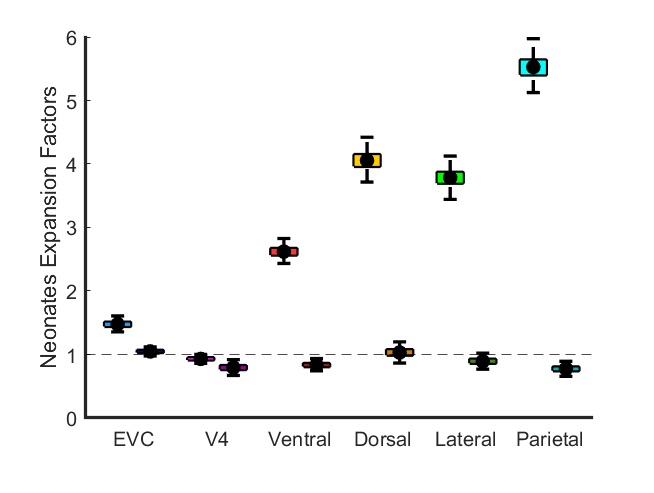

human_evc_idx = [1, 2, 3];
human_dorsal_idx =  [9, 10, 15:21];
human_lateral_idx = [11:14];
human_ventral_idx = [4:8];

monkey_evc_idx = [1, 2, 3, 4, 5];
monkey_dorsal_idx =  [11, 12, 17:21];
monkey_lateral_idx = [13:16];
monkey_ventral_idx = [6:10];

EVCcolor=[0 0 0.7];
V4color=[0.6 0 0.6];
ventralcolor=[0.6 0.1 0.1];
dorsalcolor=[0.8 .5 0]; % added V7, idk if that's right
lateralcolor=[0.2784    0.5216    0.1451];
parietalcolor=[0 0.7 0.7];
use_colorscale_human=[EVCcolor;V4color;ventralcolor;dorsalcolor;lateralcolor;parietalcolor];
use_colorscale_inv_human = flipud(use_colorscale_human);

evccolor=[0.1 0.6 1];
v4color=[1 0.2 1];
ventralcolor=[1 0.2 0.2];
dorsalcolor=[1 .8 0];
parietalcolor=[0 1 1];
lateralcolor=[0 1 0];
use_colorscale_monkey=[evccolor;v4color;ventralcolor;dorsalcolor;lateralcolor;parietalcolor];
use_colorscale_inv_monkey = flipud(use_colorscale_monkey);

evc_idx = 2:3;
v4_idx = 4;
dorsal_idx = human_dorsal_idx(1:2);
parietal_idx = human_dorsal_idx(3:end);
lateral_idx = human_lateral_idx;
ventral_idx = human_ventral_idx;
human_area_idx = {evc_idx,v4_idx,ventral_idx,dorsal_idx,lateral_idx,parietal_idx};

evc_idx = 2:3;
v4_idx = 4:5;
dorsal_idx = monkey_dorsal_idx(1:2);
parietal_idx = monkey_dorsal_idx(3:end);
lateral_idx = monkey_lateral_idx;
ventral_idx = monkey_ventral_idx;
monkey_area_idx = {evc_idx,v4_idx,ventral_idx,dorsal_idx,lateral_idx,parietal_idx};

alllabels_combined = {'EVC','V4','Ventral','Dorsal','Lateral','Parietal'};

nResampling = 1000;
d_neo = 1:size(SA_sumvd_neo,2);
d_human = 1:size(SA_sumvd_human,2);
data_monkey = zeros(length(human_area_idx),nResampling);
data_human = zeros(length(human_area_idx),nResampling);
for idx = 1:length(human_area_idx)
    for res = 1:nResampling
        y = datasample(d_neo,size(SA_sumvd_monkey,2));
        data_monkey(idx,res) = mean(mean(SA_sumvd_neo(human_area_idx{idx},y)./SA_sumvd_neo(1,y),2,'omitnan'))./mean(mean(SA_sumvd_monkey(monkey_area_idx{idx},:)./SA_sumvd_monkey(1,:),2,'omitnan'));
        y = datasample(d_human,size(SA_sumvd_neo,2));
        data_human(idx,res) = mean(mean(SA_sumvd_neo(human_area_idx{idx},:)./SA_sumvd_neo(1,:),2,'omitnan'))./mean(mean(SA_sumvd_human(human_area_idx{idx},y)./SA_sumvd_human(1,y),2,'omitnan'));
    end
end

concat_data = [];
concat_colorscale = [];
for i = 1:size(data_human,1)
    concat_data = [concat_data; data_monkey(i,:); data_human(i,:)];
    concat_colorscale = [concat_colorscale; use_colorscale_inv_human(i,:); use_colorscale_inv_monkey(i,:)];
end

g1 = sort([1:6,1:6]);
g2 = repmat(1:2,[1,6]);


figure('Renderer', 'painters', 'Position', [10 10 1500 500]);
hold on
h1=boxplot(concat_data',[g1' g2'],'factorgap',5,'colors',[0 0 0],'symbol','','Widths',0.8);
set(h1,{'linew'},{2})
h1 = findobj(gca,'Tag','Box');
for j=1:size(concat_data,1)
   % have to extract x values from boxplot in order to set xlabels
   xdat{j} = get(h1(j),'XData');
   xd(j) = (xdat{j}(3)+xdat{j}(2))/2;
   patch(get(h1(j),'XData'),get(h1(j),'YData'),concat_colorscale(j,:),'FaceAlpha',1);
end

% plotSpread(concat_data','xValues',fliplr(xd),'distributionColors',concat_colorscale*0+[.6 .6 .6],'spreadWidth',.5)
plot(fliplr(xd),nanmean(concat_data'),'k.','MarkerSize',30);
yline(1,'k--')

% take average of x values for each area to put xticklabel in the middle
xt = [];
for i = 1:length(xd)/2
    xt(i) = (xd(2*i-1) + xd(2*i))/2;
end

ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',fliplr(xt),'xticklabel', alllabels_combined,'fontsize',12);
% xlabel('Visual Areas');
ylabel('Neonates Expansion Factors');
% title('Normalization by Combined V1 Surface Area')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
ylim([0 6])